# Acoustic Index Analysis of the EigenScape Data Set

## Background

Research around the evaluation and development of soundscapes has continued to grow towards hollistic approaches to soundscape management, combining features of human evaluation and computational processing to allow stakeholders to develop and evaluate new soundscapes as well as providing tools for public engagement. However, the quantification of soundscapes still presents many challenges; Is it possible to quantify the perceptual qualities of a soundscape through computational evaluation? Is it possible to use an index to identify the emotional positivity of a soundscape? 

A major component of the soundscape research paradigm is the human affective evalution of soundscapes. The aim of much soundscape planning work is to identify how to improve the quality of soundscapes and thus improve the quality of life of those who will be exposed to those soundscapes. The aim of some soundscape research is to identify how to effectively evaluate soundscapes in a way that reflects how humans experience soundscapes, without incuring penalties related to experimental cost, time or reliability. An example of such research is work by Stevens *et al. *who evaluated the use of the Self Assessment manikin in soundscape evaluation \cite(CITE). This work builds on the use of sematic differential pairs, a technique for lexical analysis that has been used previously in the context of soundscape evaluation \cite(Sorrel, CITE).

Acoustic Indices have been developed in many cases for the purpose of analysing the biodiversity of environments by using acoustic data. Previous research has suggested that these indices can be used to draw more general conclusions about soundscapes such as the 'naturalness' of a soundscape \cite(Devos2016, ﻿Green2019). The purpose of these indicies is often to identify the features of natural sounds while being robust to or considerate of human made or mechanical sound sources such as cars and planes. An example of such an index is the Normalised Difference Soundscape Index (NDSI) which was first developed by Kasten *et al.* \cite(﻿Kasten2012). ﻿The NDSI is a the proportional relationship between the sum of the power of two separate frequency ranges, the range of 1kHz to 2kHz being used to identify 'more mechanical sounds' and the 2kHz to 11kHz region being used to identify 'more natural sounds'. The intuition behind the choice of spectral regions being that mechanical sounds tend to be slower or lower in frequency than natural sounds. 

It is commonly reported in many studies in soundscape literature that humans often have a more positive affective response to more natural soundscapes, and a more negative affetive response to industrial and mechanical soundscapes \cite(CITE). When attempting to evaluate a soundscape with metrics in proxy of direct human affective ratings, if it holds true that acoustic indicies can represent feautres of soundscapes that relate to how they are percieved such as more natural meaning more pleasant, it should be the case that humans affective evaluation of soundscapes correlates positively with the infered naturalness of acoustic index scores for these soundscapes. 

The EigenScape data set is a set of eight ambisonic recordings of eight different classes of soundscape, a total of 64 ten minute soundscape recordings that was recorded by Green in May of 2017 \cite(﻿Green2017). The dataset includes a broad range of soundscape types including:

- Beach

- Busy Street

- Park

- Pedestrian Zone

- Shopping Centre

- Train Station

- Woodland

The locations of each recording in the data-set are conveniently presented in a google map that is available through the data set repository, a copy of the map is present in figure 1.

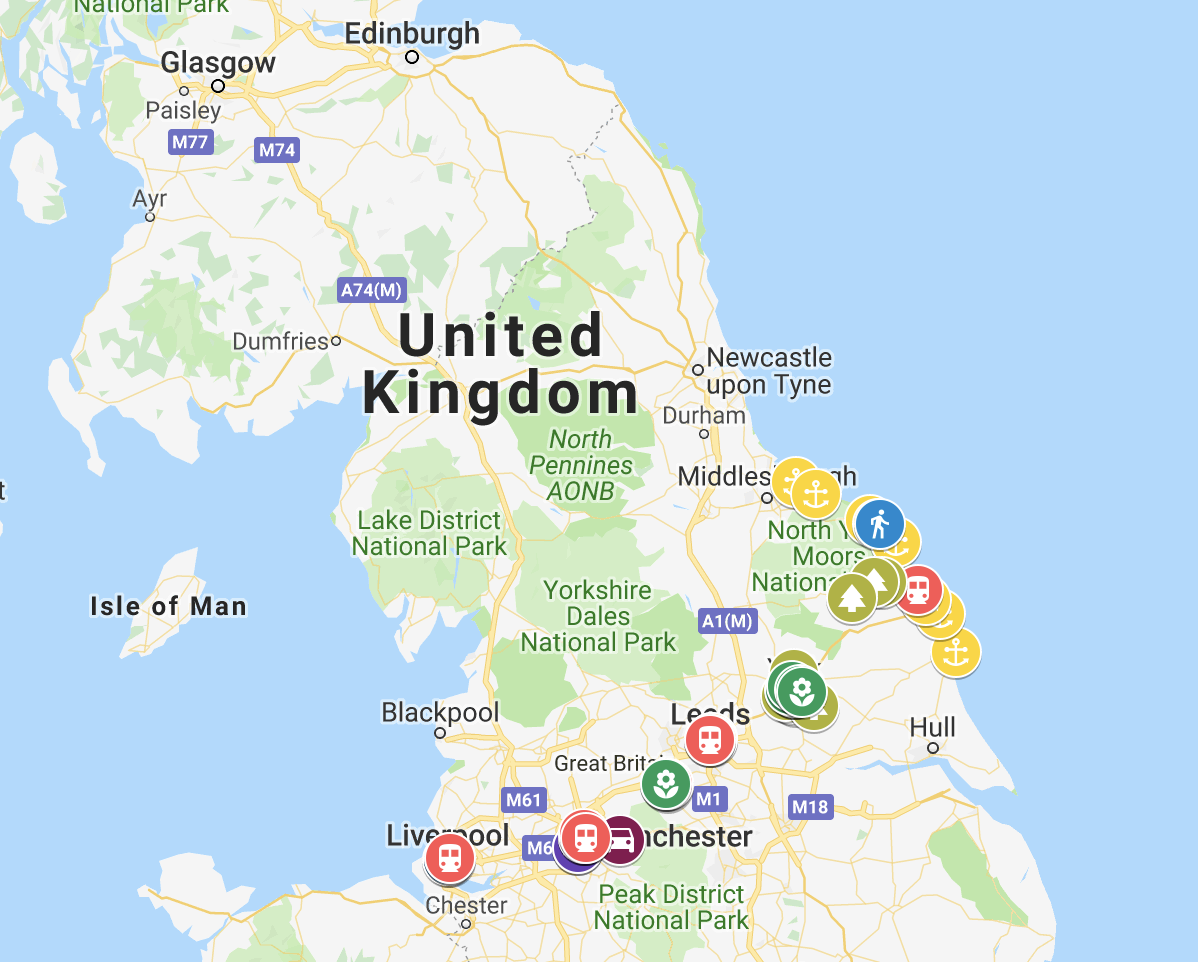

The purpose of this report is to evaluate the acoustic index rating of the EigenScape dataset, split into contiguous frames of 100 seconds. The soundscape segments that are identified as most and least natural will be used in an evaluatory soundscape experiment, where participants will classify and affectively rate their experience of the most and least 'natural' soundscape clips. The aim of this report is to identify if acoustic indices might be used to evaluate the valent quanlities of soundscapes.

### Load Data

The acoustic indices were post-processed using tools in Python. Lets load the data.

% filename = 'indices_eigenscape_5_8_19.csv';
filename = 'indices_90s.csv';
Indices = importIndices(filename);
head(Indices)

ans = 8×20 table
       filename        Acoustic_Complexity_Index__main_value    Acoustic_Complexity_Index__min    Acoustic_Complexity_Index__max    Acoustic_Complexity_Index__mean    Acoustic_Complexity_Index__median    Acoustic_Complexity_Index__std    Acoustic_Complexity_Index__var    Acoustic_Diversity_Index__main_value    Acoustic_Evenness_Index__main_value    Bio_acoustic_Index__main_value    Normalized_Difference_Sound_Index__main_value     RMS_energy__min       RMS_energy__max      RMS_energy__mean     RMS_energy__median      RMS_energy__std        RMS_energy__var       Spectral_Entropy__main_value    Temporal_Entropy__main_value
    __

## Acoustic Indices

There are a wide number of acoustic indices that have been developed to identify different acosutic features, in 2016 Devos presented a review of soundecology indicators as applied to urban soundscapes \cite(﻿Devos2016). In this work Devos evaluated the use of six different indices:

- Acoustic Complexity Index

- Normalised Difference Soundscape Index

- Bioacoustic Index

- Acoustic Diversity Index

- Acoustic Evenness Index

- Acoustic Entropy

These indicies were previously explored in the context of biodiversity assesment and landscape investigation by Sueur et al. ***CITE*** who argued that a 'utopian' vision of a single acoustic index for Biodiversity evaluation is improbable or unlikely; perhaps an index that can quantify the quality of urban soundscapes is also unlikely to be found. Devos reviewed the performance of these 6 acoustic indicators by comparing the index scores of two different urban semi-agribultural terrains, one with a close railway line and one without. The soundecology indicators were calculated by using the soundecology package that is an extyension of the R programming language ***CITE***. The use of principal component analysis on the soundscape indicators identified a strong correlation betwen acoustic entropy, AEI and ADI indicators, while a weaker correlation exists between BIO and NDSI. Following this result and the discussion by Devos, it is suggested that it should be possilble to reduce the number of indices for urban soundscape analysis down to a collection of 3 parameters, in this study we will use ADI, NDSI and acoustic entropy as this might serve to identify further variation in the data as discussed by Devos.

In order to analyse the acoustic indices of the EigenScape dataset, a python implementation of the R soundecology library was updated to work on python3; the tool was further configured to streamline the process of analysing the large number of 960 soundscape segments. The original port of the R library to Python was made available by Guyot CITE, and the original soundecology R librabry as used by Devos was originally published by Villanueva-Rivera and Pijanowski ***CITE.***

### NDSI

The normalised difference soundscapes index as discussed earlier was used by Green and Murphy in the rating of  \cite(﻿Green2019).

First, lets get the top NDSI scores 

highNDSI = sortrows(Indices, 12);
head(highNDSI(:,[1 12]))

ans = 8×2 table
          filename           Normalized_Difference_Sound_Index__main_value
    _____________________    _____________________________________________

    "Park.2.6.wav"                        -0.944445306207496              
    "QuietStreet.4.5.wav"                 -0.900095475500787              
    "QuietStreet.4.3.wav"                 -0.884304427367951              
    "QuietStreet.4.1.wav"                  -0.88240192435182              
    "QuietStreet.4.2.wav"                 -0.870039759879761              
    "BusyStreet.6.4.wav"                  -0.869314440780945              
    "QuietStreet.4.4.wav"                 -0.868537093962128              
    "BusyStreet.6.1.wav"                  -0.860780963953696              


This is interesting, because the busy street soundscapes often features heavy traffic and other very strong and dominant mechanical sounds, and yet two Park segments have the greatest negative (least natural) NDSI scores. We will investigate why this might be shortly.

Now lets get the minimum NDSI scores

tail(highNDSI(:,[1 12]))

ans = 8×2 table
         filename         Normalized_Difference_Sound_Index__main_value
    __________________    _____________________________________________

    "Woodland.5.4.wav"                  0.709630700845332              
    "Woodland.6.3.wav"                   0.71735750195541              
    "Woodland.5.6.wav"                  0.749331109184892              
    "Woodland.8.1.wav"                  0.782652471533989              
    "Woodland.2.6.wav"                  0.820479355064129              
    "Woodland.5.3.wav"                  0.836479489109228              
    "Woodland.4.6.wav"                  0.861008777154454              
    "Woodland.5.5.wav"                  0.901128445405205              


Maybe it seems more intuitive that woodland recordings would get a high NDSI score.

Lets have a look at how the NDSI distribution of different soundscape locations.

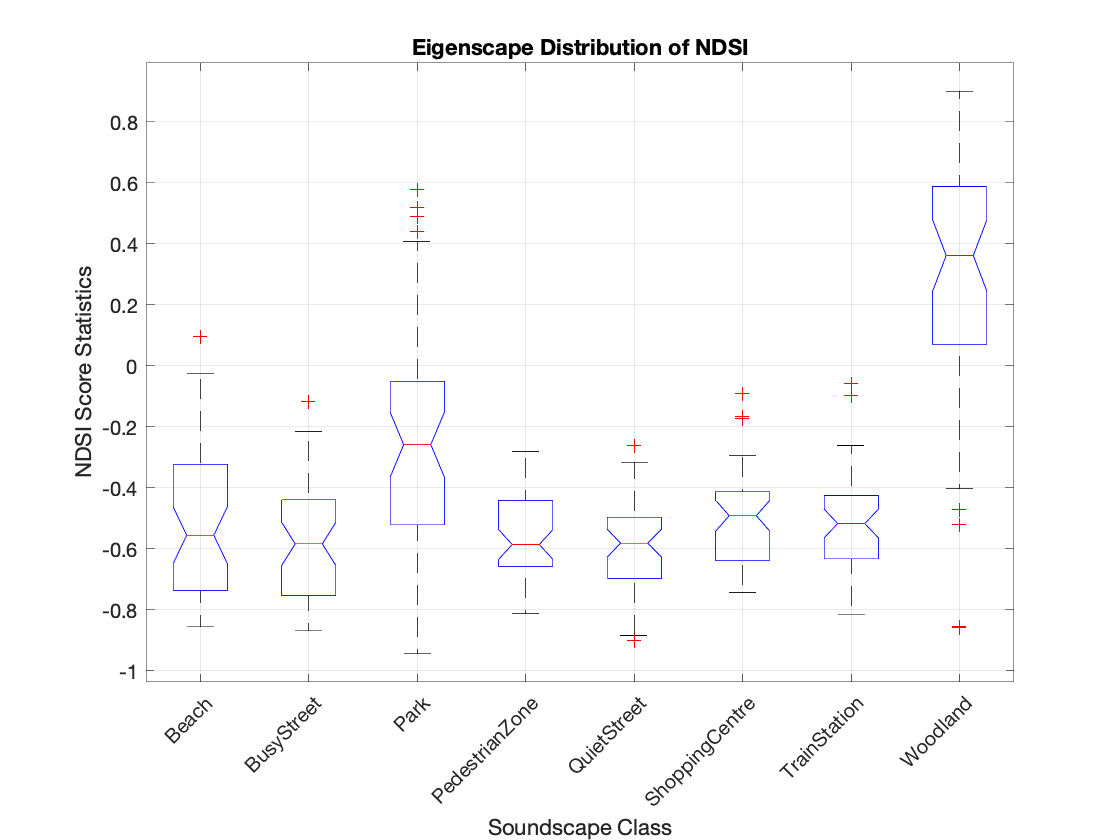

boxplotIndex(highNDSI(:,[1 12]), "NDSI");

The boxplot above would suggest that the two presumably more 'natural' soundscape locations, the woodland and then park, have a much wider NDSI distribution than the other 6 classes who all appear to have predominantly negative NDSI scores. It might be intuitive that the train station, busy street and quiet street classes have large negative NDSI values, and that the range of those scores is predominantly low compared to the 'more natural' soundscapes; the shopping centre might be a surprise, as typical human sounds achieve a negative NDSI score, this might suggest that human sounds do not fit into the natural catagory but are also not entirely mechanical. The beach class also appears to have a wholy negative or low positive NDSI score, and it might be that the score is penalised by the low-frequency noise of the wind and the sea. The broad range of woodland soundscape NDSI values might be caused by instances where the woodland is in an area surrounded by evnironmental noise sources such as roads, railways and flight paths. 

Lets review the NDSI for each clas

For example, on close inspection of the woodland segment with the most negative NDSI score, Woodland.7.03.wav, it would appear that despite a large amount of bird song the clip clearly contains both the sound of a steam train, a steam train whistle and a car pass-by. In the spectrogram below of this woddland scene, the power of the train whistle at 31 seconds and around 1kHz is clearly more powerful that the sounds (presumably bird-song) across the track in the 2kHz to 9kHz region. However it is perhaps unlikely that humans will rate this soundscape as 'unpleasant', though this will be evaluated in future work.

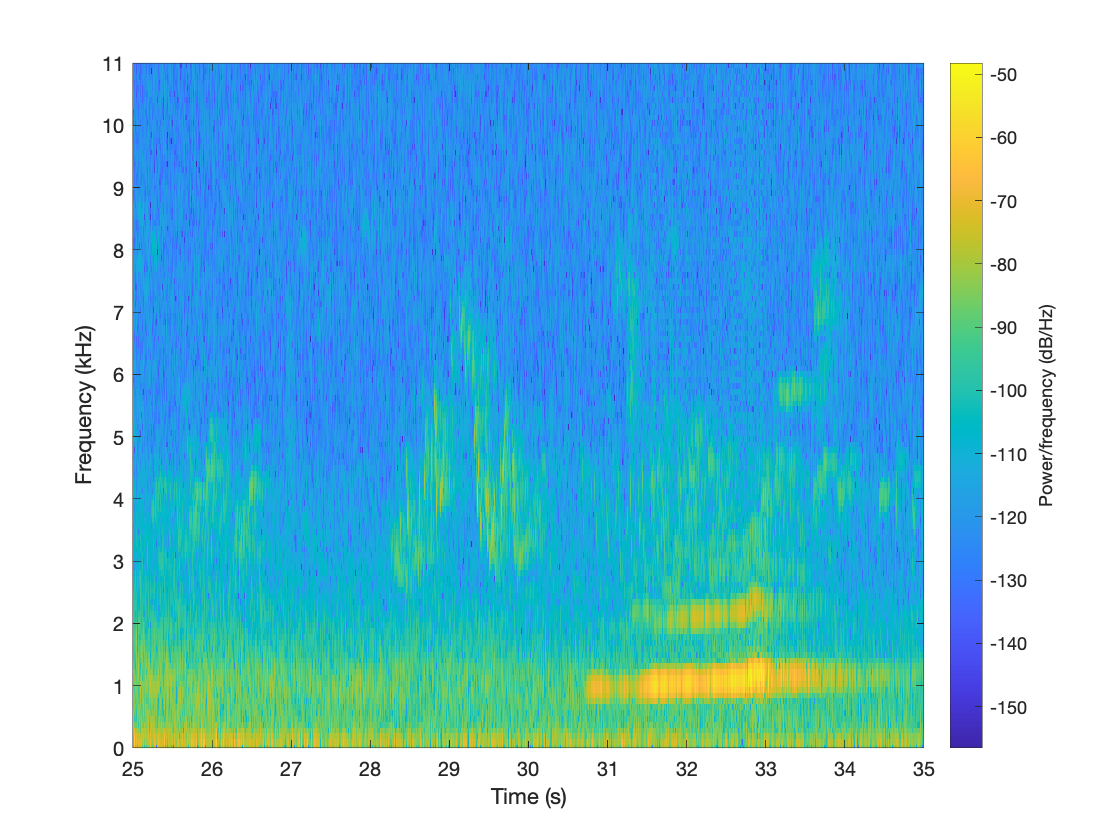

[NegativeNDSIWoodland, wnfs] = audioread('/Volumes/Data/EigenScape/audio/Woodland/Woodland.7.03.wav');
sound(NegativeNDSIWoodland(:, 1), wnfs);
spectrogram(NegativeNDSIWoodland(:,1), kaiser(256,5), 220, 512, wnfs, 'yaxis');
ylim([0 11]);
xlim([25 35]);

When reviewing the most positive woodland segment in the spectrogram below, Woodland.5.14.wav, it is clear to see and head that higher frequency birdsong dominates the soundscape.Future work will identifty if this is considered a more pleasant soundscape than Woodland.7.03.wav, but it is clear that NDSI is performing as might be expected from the algorithm description. It would appear there are less mechanical sounds in the latter woodland segment than the former. 

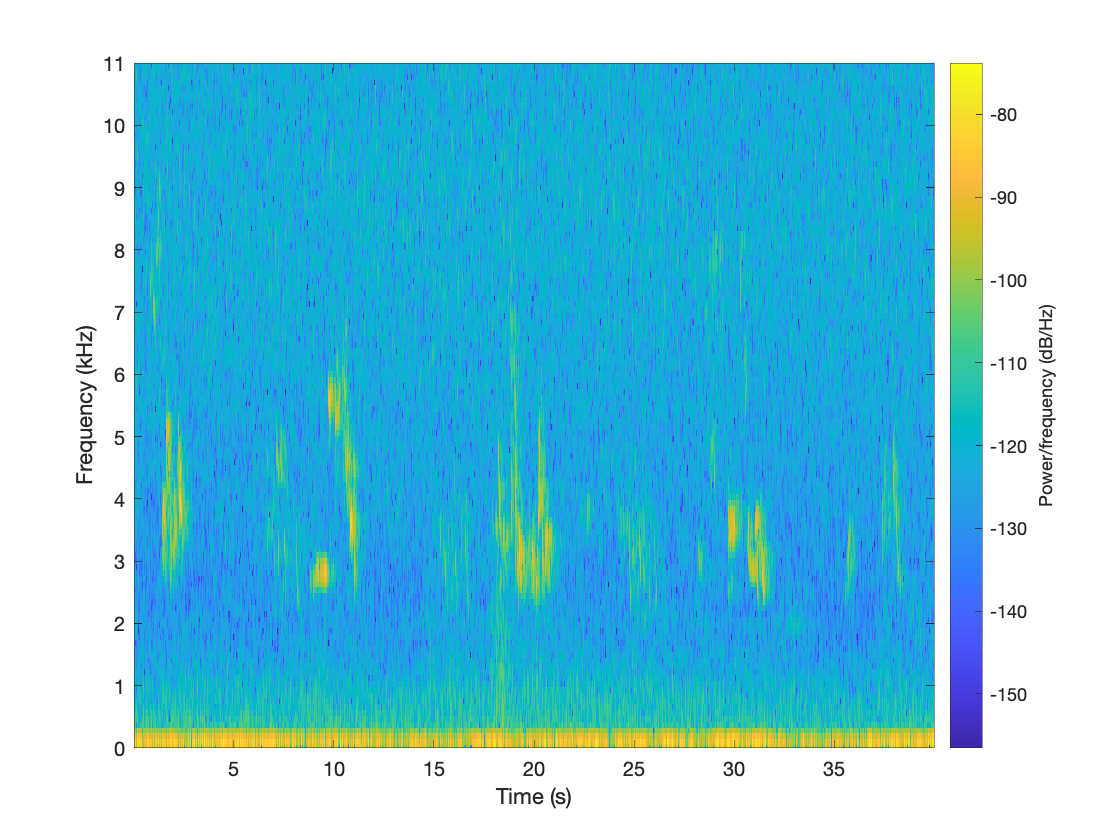

[PositiveNDSIWoodland, wpfs] = audioread('/Volumes/Data/EigenScape/audio/Woodland/Woodland.5.14.wav');
sound(PositiveNDSIWoodland(:, 1), wpfs);
spectrogram(PositiveNDSIWoodland(:,1), kaiser(256,5), 220, 512, wpfs, 'yaxis');
ylim([0 11]);

However, despite the positive performance in woodland scene classification with NDSI, it is clear from the boxplots above that the other 7 classes of soundscape all have a negative mean NDSI score. 

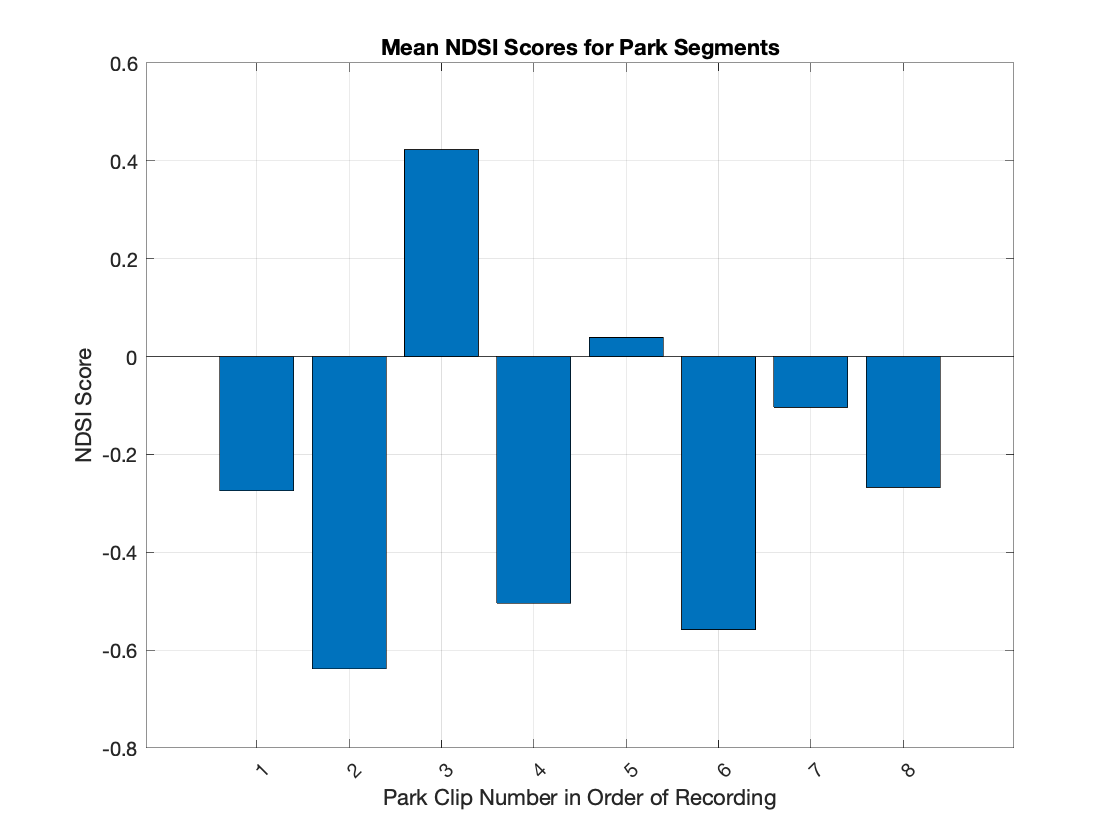

for nPark = 1 : 8
    parkNDSI = highNDSI(contains(highNDSI(:,1).Variables, "Park."+num2str(nPark)) == true, [1 12]);
    parkNDSI = sortrows(parkNDSI, 1);
    mindex(nPark) = mean(parkNDSI.Normalized_Difference_Sound_Index__main_value);
end
bar(mindex);
title("Mean NDSI Scores for Park Segments");
xtickangle(45);
grid('on');
ylabel("NDSI Score");
xlabel("Park Clip Number in Order of Recording");

% legend(string(1:8));

### Acoustic Diversity Index

The acoustic diversity index (ADI) is Shannon index of the proportion of energy above -50dBFS in the spectrogram of a soundscape segment clip, of which the spectrogram is binned into 1kHz segments. As such the ADI is the proportional representation of energy across the frequency bands above the threshold.

highADI = sortrows(Indices, 9);
head(highADI(:,[1 9]))

ans = 8×2 table
            filename            Acoustic_Diversity_Index__main_value
    ________________________    ____________________________________

    "Beach.2.3.wav"                      0.697114034244402          
    "PedestrianZone.8.1.wav"             0.899177675200651          
    "BusyStreet.4.4.wav"                 0.927946222451566          
    "PedestrianZone.3.4.wav"               1.0040594397341          
    "TrainStation.7.6.wav"                1.03818428541392          
    "PedestrianZone.3.3.wav"              1.04935590908637          
    "PedestrianZone.5.5.wav"              1.06296189992859          
    "PedestrianZone.8.2.wav"              1.08490034949487          


tail(highADI(:,[1 9]))

ans = 8×2 table
         filename         Acoustic_Diversity_Index__main_value
    __________________    ____________________________________

    "Park.7.4.wav"                   2.2898453862509          
    "Woodland.5.6.wav"              2.29254951067493          
    "Woodland.5.5.wav"              2.29827392967484          
    "Woodland.6.4.wav"              2.29894465802326          
    "Woodland.6.2.wav"              2.29974153418884          
    "Woodland.6.5.wav"              2.30021086983434          
    "Woodland.5.1.wav"              2.30076793433531          
    "Woodland.5.4.wav"              2.30101725288149          


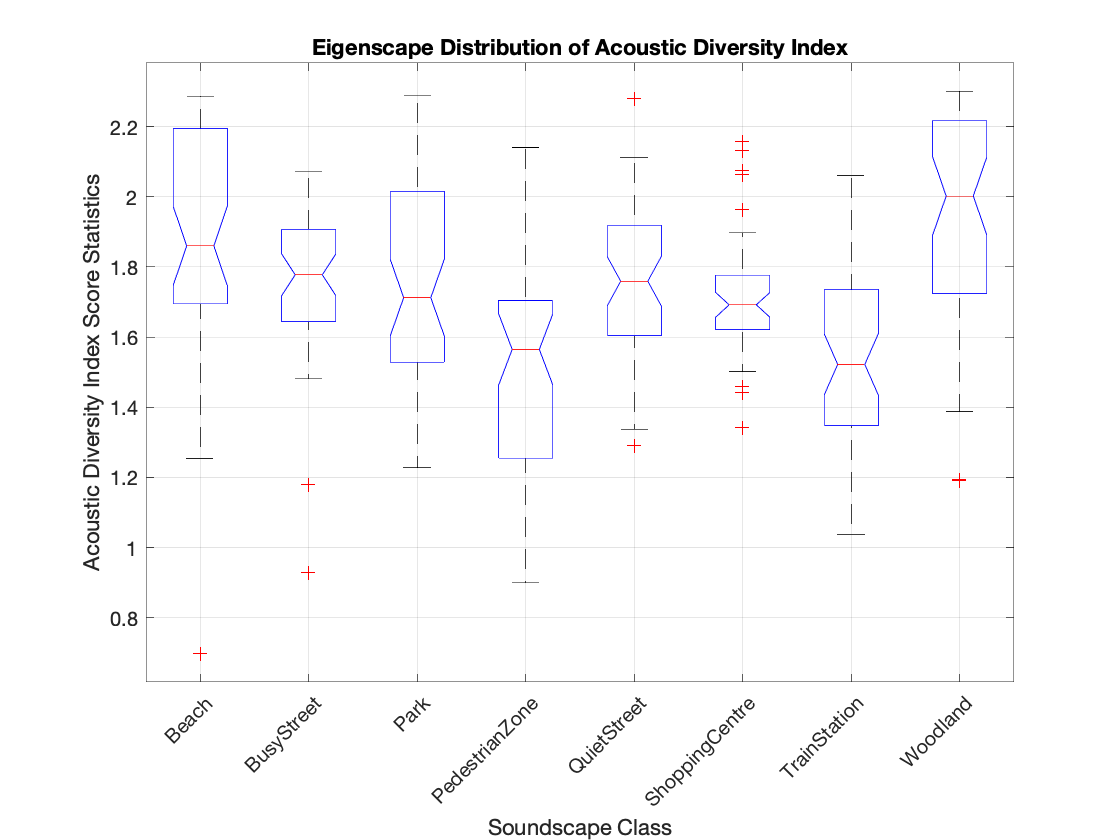

boxplotIndex(highADI(:,[1 9]), "Acoustic Diversity Index");

### Acoustic Entropy

totalEntropy = Indices(:,"Spectral_Entropy__main_value").Variables .* Indices(:,"Temporal_Entropy__main_value").Variables;
Indices.Total_Entropy = totalEntropy;
highAE = sortrows(Indices, 21);
head(highAE(:,[1 21]))

ans = 8×2 table
            filename              Total_Entropy  
    ________________________    _________________

    "PedestrianZone.3.1.wav"    0.631294913490195
    "Beach.3.3.wav"             0.632200374988404
    "Beach.3.2.wav"             0.632375921526138
    "Beach.3.1.wav"             0.634121189094657
    "Beach.3.6.wav"             0.636835255089708
    "Beach.3.4.wav"             0.637325002689514
    "Beach.3.5.wav"             0.638883923448596
    "ShoppingCentre.3.3.wav"    0.639832228091113


tail(highAE(:,[1 21]))

ans = 8×2 table
         filename           Total_Entropy  
    __________________    _________________

    "Woodland.6.1.wav"    0.947085091642304
    "Woodland.5.2.wav"    0.954932732544558
    "Woodland.5.4.wav"    0.956085441563493
    "Woodland.6.3.wav"    0.957088772510232
    "Woodland.5.3.wav"    0.957337751977674
    "Woodland.5.5.wav"    0.961940278690284
    "Woodland.5.1.wav"    0.963596496066209
    "Woodland.5.6.wav"    0.967454481012418


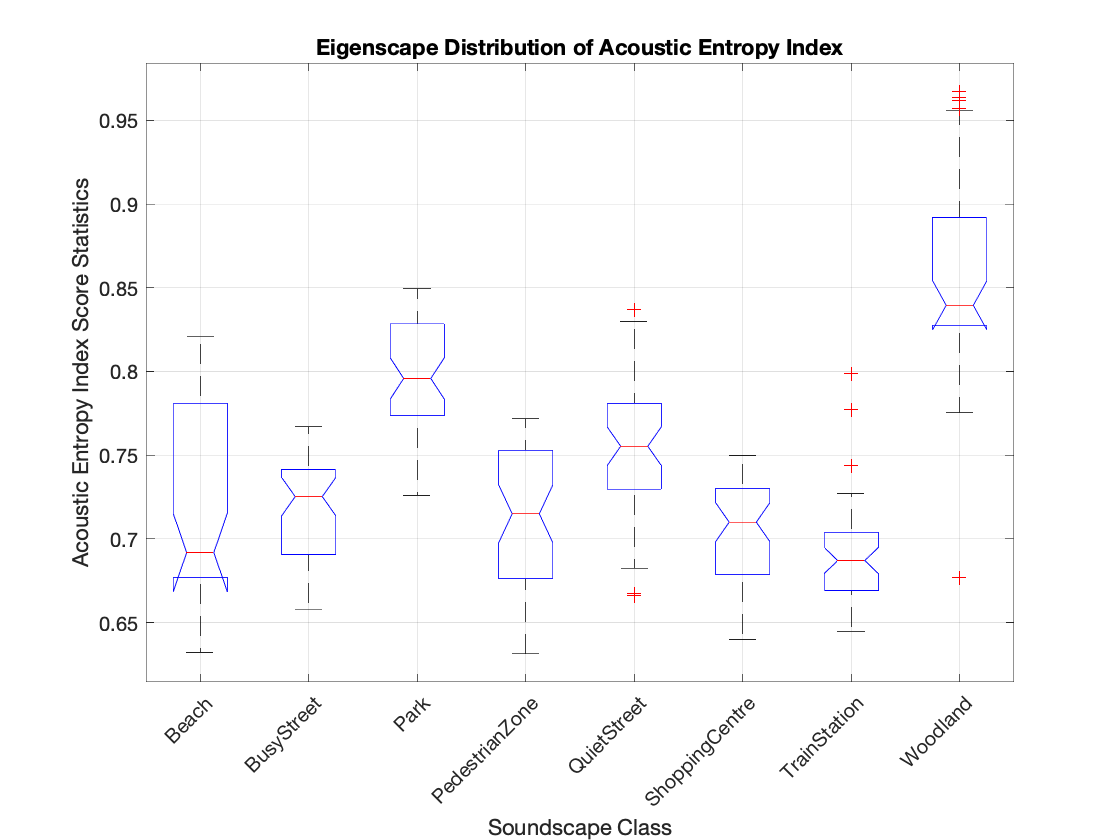

boxplotIndex(highAE(:,[1 21]), "Acoustic Entropy Index");

### Sound Clip Exploration

Unsurprisingly the most mechanical and natural soundscapes sound very similar and often are subdivisions of the same recording environment. What is more surprising is that it is actually the more sparse acoustic environments that are identified as the most extreme mechanical and natural soundscapes. Ideally it would be good to have the most extreme soundscapes from each soundscape type; unfortunately, many of the soundscapes classes in this data set do not have a positive NDSI index at all. 

### References

### Functions

function boxplotIndex(table, parameter)
% highNDSI(:,[1 12]);
types = ["Beach" "BusyStreet" "Park" "PedestrianZone" "QuietStreet" "ShoppingCentre" "TrainStation" "Woodland"];
fileNames = table(:,1).Variables;
index = table(:,2).Variables;
for index = 1 : length(types)
    data(:, index) = table(contains(table(:,1).Variables, types(index)) == true, 2).Variables';
end
boxplot(data,'Notch','on','Labels', types,'Whisker',1);
title("Eigenscape Distribution of " + string(parameter));
xtickangle(45);
xlabel("Soundscape Class");
ylabel(string(parameter) + " Score Statistics");
grid("on");
end